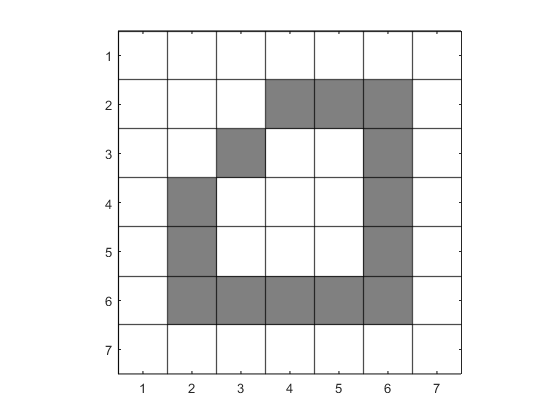

clear

Nx = 7;
Ny = 7;
img = uint8(255 * ones(7, 7, 3));
img(2,4:6,:) = 128;
img(6,2:6,:) = 128;
img(3:5,6,:) = 128;
img(4:5,2,:) = 128;
img(3,3,:) = 128;

n = 1;
plotraster(img)
filename = sprintf('../images/floodfill_example_%1i.png', n);
exportgraphics(gcf,filename,'Resolution',300) 

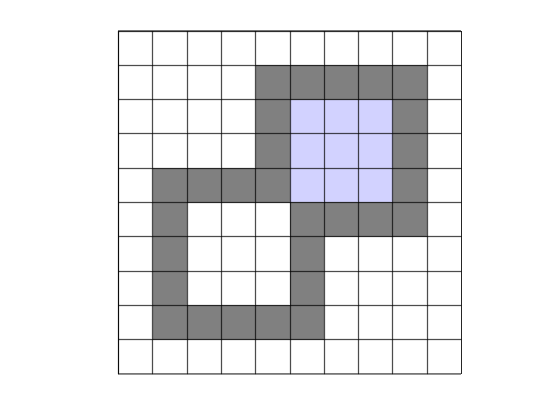

blue = [210, 210, 255];
darkblue = [0, 0, 255];
x0 = 4;
y0 = 4;
target = [255, 255, 255];
replacement = blue;
% 
% Q = [ x0, y0 ];
% while isempty(Q) == 0
%     pixel = Q(end,:);
%     Q(end,:) = [];
%     if img(pixel(2), pixel(1), 1) == target(1) && ...
%             img(pixel(2), pixel(1), 2) == target(2) && ...
%             img(pixel(2), pixel(1), 3) == target(3)
%         img(pixel(2), pixel(1), :) = replacement;
%         Q = [ Q ; 
%             pixel(1) + 1, pixel(2) ; 
%             pixel(1) - 1, pixel(2) ;
%             pixel(1), pixel(2) + 1 ;
%             pixel(1), pixel(2) - 1 ];
% 
%         img(pixel(2), pixel(1), :) = darkblue;
%         n = n + 1;
%         plotraster(img)
%         filename = sprintf('../images/floodfill_example_%1i.png', n);
%         exportgraphics(gcf,filename,'Resolution',300) 
%         img(pixel(2), pixel(1), :) = blue;
%     end
% end


figure()
Nx = 10;
Ny = 10;
img = uint8(255 * ones(Nx, Ny, 3));
img(2,5:9,:) = 128;
img(5,2:5,:) = 128;
img(6,6:9,:) = 128;
img(9,2:6,:) = 128;
img(3:4,5,:) = 128;
img(3:5,9,:) = 128;
img(6:8,2,:) = 128;
img(7:8,6,:) = 128;

img = floodfill(img, 7, 4, [255,255,255], blue);

plotraster(img)
xticks([])
yticks([])
exportgraphics(gcf,'../images/flood_fill_tight_corner.png','Resolution',300) 

function plotraster(img)

[Ny, Nx, ~] = size(img);

image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
hold off

xticks(1:1:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])

end


function R = floodfill(R, x0, y0, target, replacement)

Q = [ x0, y0 ];
while isempty(Q) == 0
    pixel = Q(end,:);
    Q(end,:) = [];
    if R(pixel(2), pixel(1), 1) == target(1) && ...
            R(pixel(2), pixel(1), 2) == target(2) && ...
            R(pixel(2), pixel(1), 3) == target(3)
        R(pixel(2), pixel(1), :) = replacement;
        Q = [ Q ; 
            pixel(1) + 1, pixel(2) ; 
            pixel(1) - 1, pixel(2) ;
            pixel(1), pixel(2) + 1 ;
            pixel(1), pixel(2) - 1 ];
    end
end

end